# Finding a 2D SSM from real measurements

This is an example of how to reconstruct a slow 2D manifold from measurements of a mechanical system using delay embedding. In this example, we consider tip acceleration measurements from a shaker ringdown test on a beam with a bolted lap joint [1]. Oscillations are assumed to converge onto a 2D spectral submanifold (SSM), which will be identified and used for model reduction.

clearvars
close all

[1] Kosova G. et al. (2021) Nonlinear System Identification of a Jointed Structure Using Full-Field Data: Part II Analysis. In: Kerschen G., Brake M.R., Renson L. (eds) Nonlinear Structures & Systems, Volume 1. Conference Proceedings of the Society for Experimental Mechanics Series. Springer, Cham. https://doi.org/10.1007/978-3-030-47626-7_27

## Experimental Data

We will divide the data into a training set, for model fitting, and a test set, for validation. In this case the experimental data consists of two measurements, and we will use one trajectory as the training set and another one as the test set.

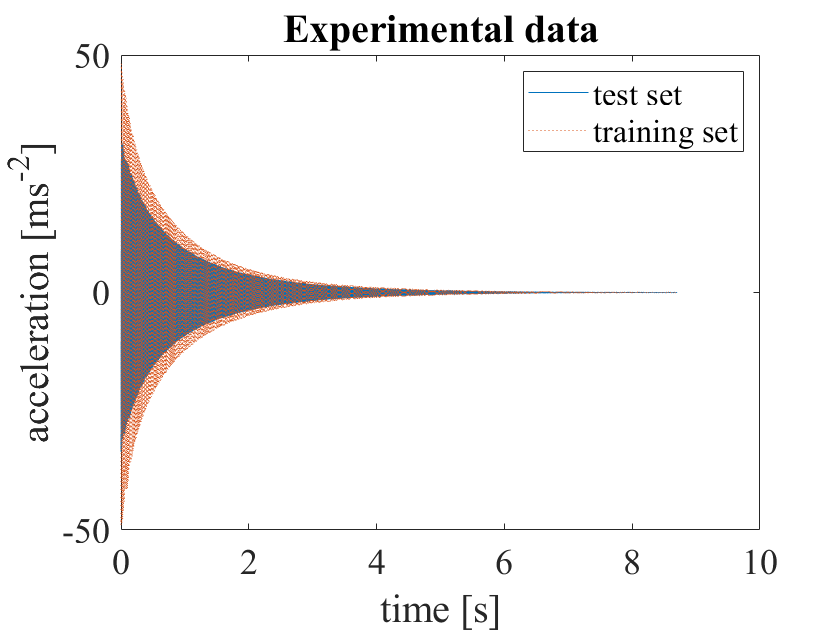

load beamData
indTest = [1];
indTrain = [2];

dt = mean(diff(xScalar{1,1}(1,:))); % dt same in all experiments
tEnd = max(xScalar{1,1}(1,:)); % Same in both measurements

plot(xScalar{1,1}, xScalar{1,2}, xScalar{2,1}, xScalar{2,2}, ':');
xlabel('time [s]'); ylabel('acceleration [ms^{-2}]'); legend({'test set', 'training set'})
set(gca,'fontname', 'times'); set(gca,'fontsize', 18); title('Experimental data')

## Delay embedding

Now we transfer to an observable space by arranging the scalar measurements in a space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space. The dimensionality of the observable space can be further expanded with the parameter `overEmbed` to facilitate recognition of the manifold from data.

We form a multi-dimensional observable by stacking $d$ subsequent scalar measurements in a vector, and we will later use the trajectories in this augmented space for the manifold fitting.


$$\left[
\begin{array}{c}
x^{0} \\ \vdots \\ x^{i} \\ \vdots \\ x^{d}
\end{array} 
\right] = 
\left[
\begin{array}{c}
x(t^k) \\ \vdots \\ x(t^k+i\Delta t) \\ \vdots \\ x(t^k+d\Delta t)
\end{array} 
\right]$$


overEmbed = 100;
shiftSteps = 1;
SSMDim = 2;

xData = coordinates_embedding(xScalar, SSMDim, 'OverEmbedding', overEmbed, 'ShiftSteps', shiftSteps);

The 105 embedding coordinates consist of the measured state and its 104 time-delayed measurements.


## Data filtering

We need to make sure that the data that we use to identify the slow manifold lies close to it. We can do this by plotting a spectrogram of the beam tip displacement. In general, there may be many vibratory modes present at first, but the faster ones quickly die out. 

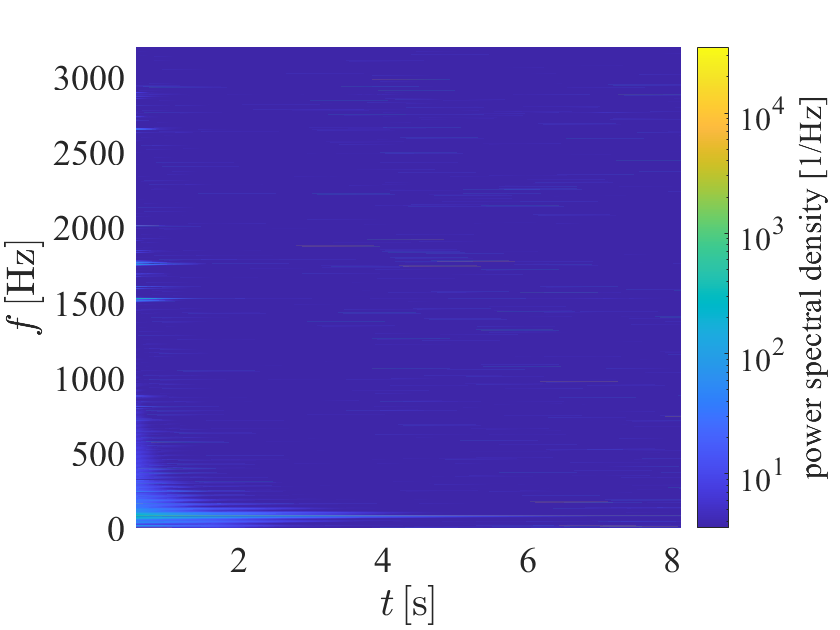

showSpectrogram(xScalar(indTrain,:), 1);

Next, we use the information from the spectrogram to remove the first part of the training data. After the first few oscillations have passed, there is one dominant mode left in the frequency spectrum. We keep only the data in the time interval `sliceInt`.

sliceInt = [0.1, tEnd];
xDataTrunc = sliceTrajectories(xData, sliceInt);

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

The eigenspace $V_e$ of the two slowest modes is unknown in this case. Trajectories are assumed to lie close to an invariant manifold that is tangent to this eigenspace, as shown in the figure below.

 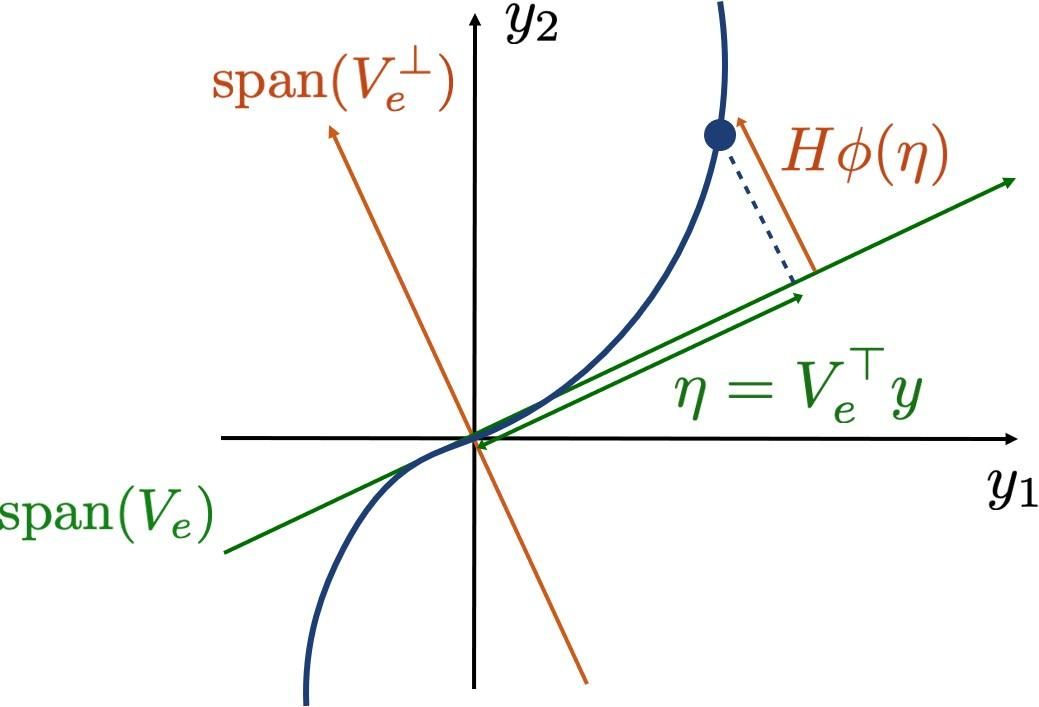

We therefore seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimising a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top - H\phi_{m,2:M}(V_e^\top y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMparametrization`.

SSMOrder = 1;
[V, SSMFunction, mfdInfo] = IMparametrization(xDataTrunc(indTrain,:), SSMDim, SSMOrder);

## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the plane. 

yData = getProjectedTrajs(xData, V);
yDataTrunc = getProjectedTrajs(xDataTrunc, V);

We plot the test and training set trajectories projected onto the plane.

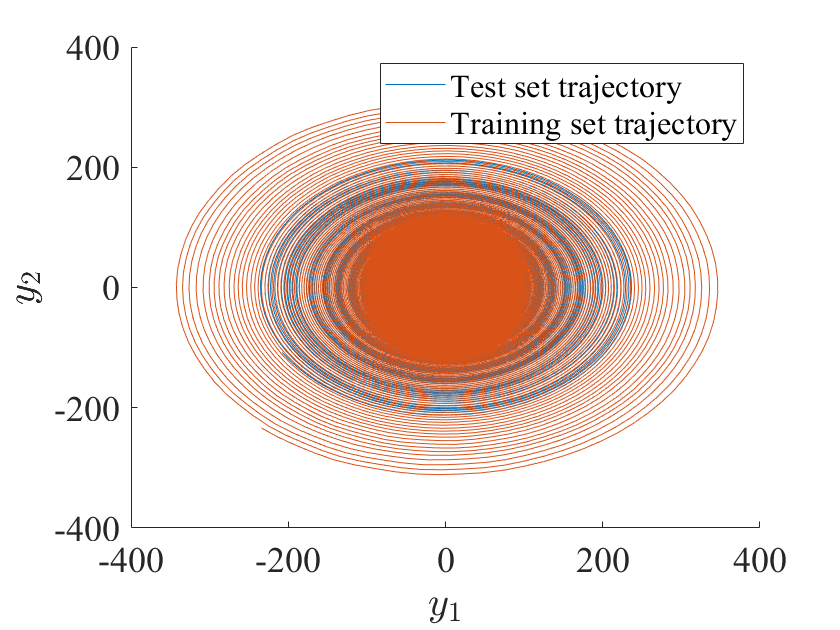

plotReducedCoords(yData);
legend({'Test set trajectory', 'Training set trajectory'})

Furthermore, we draw the end tip component of the manifold shape along with the trajectory from the training set. 

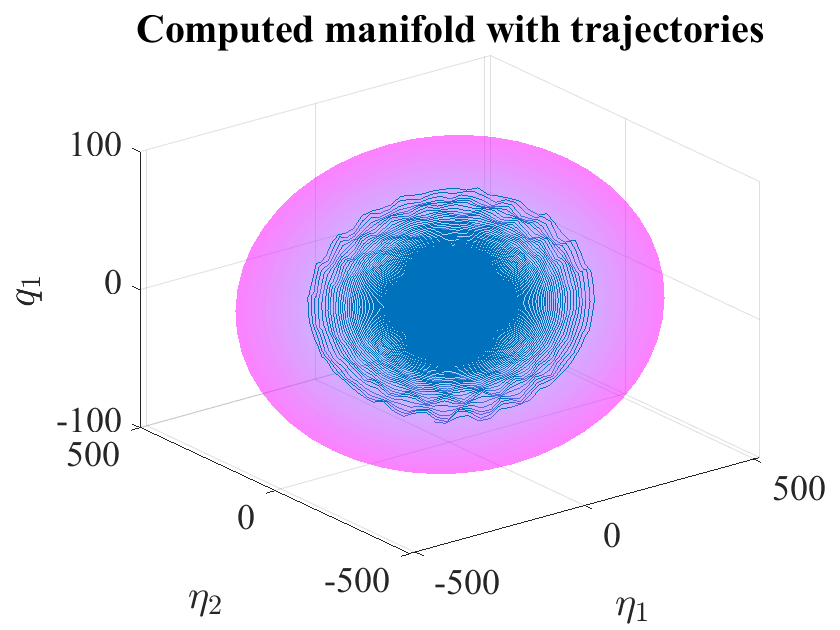

plotSSMWithTrajectories(xData(indTrain,:), SSMFunction, 1, V, 50, 'SSMDimension', SSMDim)

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMdynamics_flow` fits a polynomial map


$$\dot{y} = W_r \phi(y)$$


where $\phi(y)$ again computes a vector of all monomials of $y$, and $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics on a normal form, and seek a map $N$ fulfilling


$$\dot{z} = N(z) \approx Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ containing coefficients for the nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(y) \approx y + W_t \phi(y)$$


[~,Tinv,N,T,NormalFormInfo] = IMdynamics_flow(yDataTrunc(indTrain,:), 'R_PolyOrd', 3, 'style', 'normalform');

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1         0.069021                          2.43
     1           5         0.060102    0.000863855           3.73  
     2           6        0.0556421              1           2.21  
     3           7        0.0535349              1           1.22  
     4           8        0.0522649              1          0.305  
     5           9        0.0522037              1          0.254  
     6          10        0.0521108              1         0.0263  
     7          11        0.0521096              1        0.00467  
     8          12        0.0521096              1        0.00173  
     9          13        0.0521096              1        0.00128  

Local mini

We transform the initial condition of our test trajectory according to the obtained change of coordinates, and integrate our reduced order evolution rule to predict the development of the trajectory. 

zData = transformComplex(Tinv, yDataTrunc);
[zRec, xRecNormal] = integrateFlows(N, zData, @(q) SSMFunction(T(q)));
yRecNormal = transformComplex(T, zRec);

## Evaluation of reduced dynamics

The error RRMSE is computed as the average distance of the predicted trajectory to the actual one in the full state space.

[reducedTrajDist, fullTrajDist] = computeRecDynErrors(yRecNormal, xRecNormal, yDataTrunc, xDataTrunc);
RRMSE_normal = mean(fullTrajDist(indTest))

RRMSE_normal =      0.054622


We plot the true test set trajectory in the reduced coordinates and compare it to the prediction. 

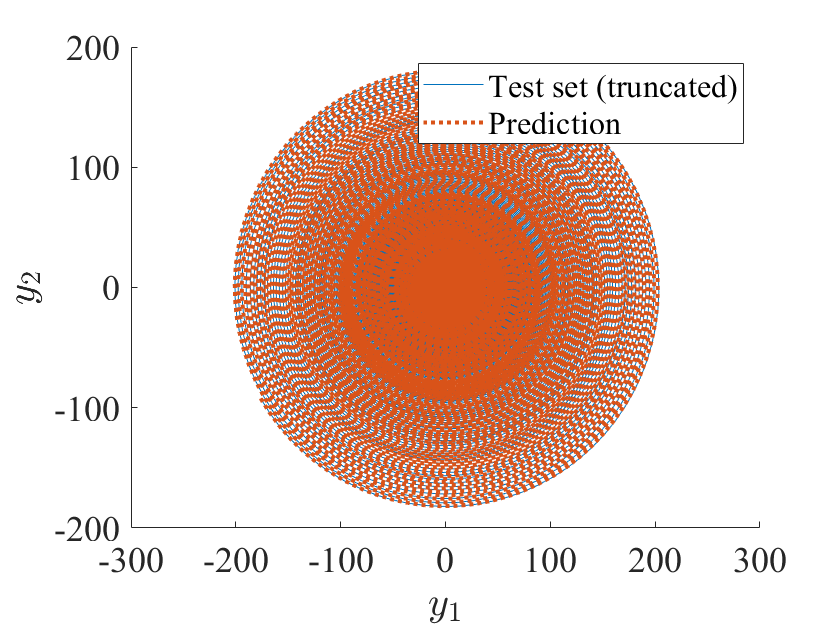

plotReducedCoords(yDataTrunc(indTest(1),:), yRecNormal(indTest(1),:))
legend({'Test set (truncated)', 'Prediction'})

We also plot the measured and predicted tip displacement. The reduced model seems to do well on previously unseen data, provided that it is initalized close to the 2D manifold.

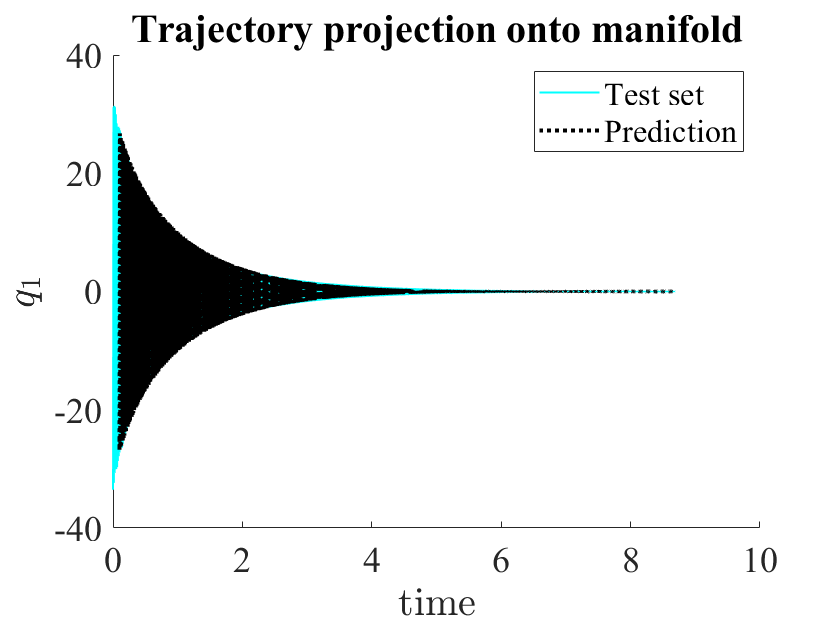

plotReconstructedTrajectory(xData(indTest(1),:), xRecNormal(indTest(1),:), 1, 'c')
legend({'Test set', 'Prediction'})

Finally we estimate the eigenvalues of the linearized system.

normalFormEigenvalues = computeEigenvaluesFlow(NormalFormInfo)

normalFormEigenvalues =      -0.88465 +     503.92i
     -0.88465 -     503.92i


## Backbone curves

With the knowledge of the coefficients of the normal form, we extract backbone curves for the instantaneous damping and frequency.

N_info = NormalFormInfo.N;
[damp,freq] = nonres_normalform(N_info.coeff,N_info.exponents);

The data-driven polar normal form dynamics reads:

                         1          r^2  
                      ________    _______

    \dot{r}/r =       -0.88465    -3.8818
    \dot{\theta} =      503.92    -5.7874

Notation: z = r*exp(1i*\theta) where r is the amplitude and \theta the phase; r^k is the k-th power of r.


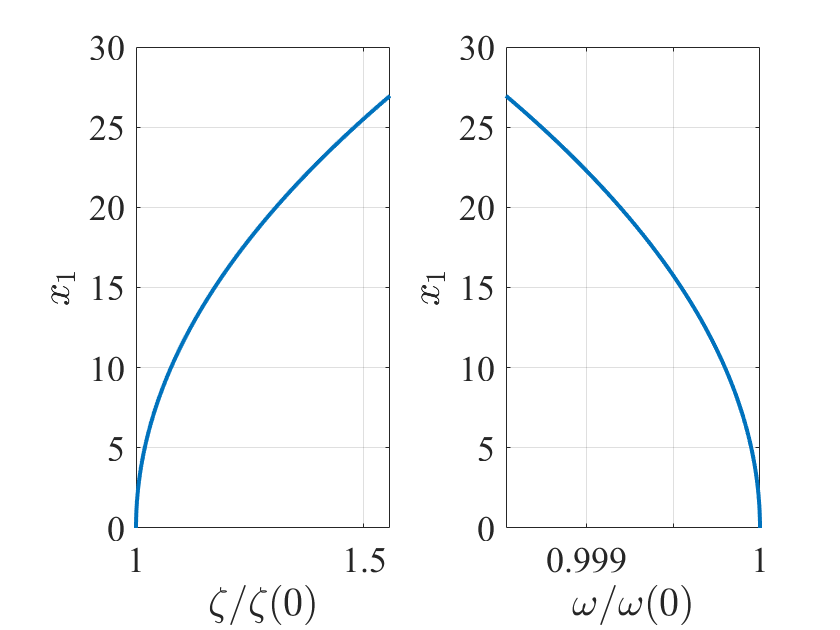

figure
maxRho = abs(zData{indTest(1),2}(1,1));
backbonecurves(damp, freq, SSMFunction, T, 1, maxRho, 'norm');